## 以整体优化为模型，探究单级DPD的线性化能力

## Algorithm 1:Feedforward Neural Network

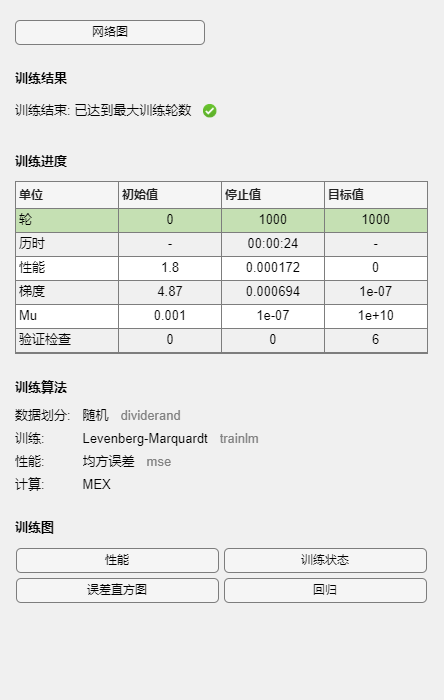

clear;
% 读取文件并处理数据
[Data_matrix,dim]=ReadFile_Original();
% 根据需要选取原始数据
Sys_x_i=Data_matrix(:,1);Sys_x_q=Data_matrix(:,2);
Sys_y_i=Data_matrix(:,15);Sys_y_q=Data_matrix(:,16);
Sys_input = Sys_x_i + 1i * Sys_x_q;
Sys_output = Sys_y_i + 1i * Sys_y_q;

% 设置输入/输出矩阵
M=7; % Memory Depth
X = zeros(2*(M + 1), dim-M);
for j = 1:length(Sys_y_i) - M
    X(:, j) = [Sys_y_i(j : j + M); Sys_y_q(j : j + M)];
end
Y = [Sys_x_i(M + 1 : end)'; Sys_x_q(M + 1 : end)'];

% 调整参数和训练模型
net = feedforwardnet(10);% 神经元数量
FNN = train(net, X, Y);


% 查看单级DPD的模型性能
Y_pred = sim(FNN, X);
a = Y_pred(1, :) + Y_pred(2, :) * 1i; % PA输出预测值
b = Y(1, :) + Y(2, :) * 1i; % PA输出值
nmse_DPD = NMSE_dB(a, b)

nmse_DPD = -36.3644

nmse_DPD = -36.3644

nmse_DPD = Get_nmse_DPD(UnPack(a),UnPack(b))
fprintf('单级DPD的NMSE为 %f dB', nmse_DPD);

单级DPD的NMSE为 -36.364358 dB

save('Algorithm_B\Alg_Whole.mat', 'FNN','-append');

## Algorithm 2:SVM

clear;
% 读取文件并处理数据
[Data_matrix,dim]=ReadFile_Original();
% 根据需要选取原始数据
PA1_x_i=Data_matrix(:,3);PA1_x_q=Data_matrix(:,4);
PA1_y_i=Data_matrix(:,7);PA1_y_q=Data_matrix(:,8);
PA1_input = PA1_x_i + 1i * PA1_x_q;
PA1_output = PA1_y_i + 1i * PA1_y_q;

% 设置输入/输出矩阵
M=7; % Memory Depth
X = zeros(2*(M + 1), dim-M);
for j = 1:length(PA1_y_i) - M
    X(:, j) = [PA1_y_i(j : j + M); PA1_y_q(j : j + M)];
end
X = X.';
Y_i = PA1_x_i(M + 1 : end);
Y_q = PA1_x_q(M + 1 : end);
XY = [X, Y_i, Y_q];

% 在APP上训练模型，并将模型导出到工作区
% load('Algorithm_B/Alg_PA1.mat');

% 查看单级DPD的模型性能
y_model = SVM_I.predictFcn(X) + SVM_Q.predictFcn(X) * 1i;
y_measure = Y_i + Y_q * 1i;
nmse_DPD = NMSE_dB(y_model, y_measure);
fprintf('单级DPD的NMSE为 %f dB', nmse_DPD);

单级DPD的NMSE为 -19.673791 dB

save('Algorithm_B\Alg_PA1.mat', 'SVM_I', 'SVM_Q','-append');

## Algorithm 3:Tree

clear;
% 读取文件并处理数据
[Data_matrix,dim]=ReadFile_Original();
% 根据需要选取原始数据
PA1_x_i=Data_matrix(:,3);PA1_x_q=Data_matrix(:,4);
PA1_y_i=Data_matrix(:,7);PA1_y_q=Data_matrix(:,8);
PA1_input = PA1_x_i + 1i * PA1_x_q;
PA1_output = PA1_y_i + 1i * PA1_y_q;

% 设置输入/输出矩阵
M=7; % Memory Depth
X = zeros(2*(M + 1), dim-M);
for j = 1:length(PA1_y_i) - M
    X(:, j) = [PA1_y_i(j : j + M); PA1_y_q(j : j + M)];
end
X = X.';
Y_i = PA1_x_i(M + 1 : end);
Y_q = PA1_x_q(M + 1 : end);
XY = [X, Y_i, Y_q];

% 在APP上训练模型，并将模型导出到工作区
% load('Algorithm_B/Alg_PA1.mat');

%  Check Modeling Performance and Save Models
y_model = Tree_I.predictFcn(X) + Tree_Q.predictFcn(X) * 1i;
y_measure = Y_i + Y_q * 1i;
nmse_DPD = NMSE_dB(y_model, y_measure);
fprintf('单级DPD的NMSE为 %f dB', nmse_DPD);
save('Algorithm_B\Alg_PA1.mat', 'Tree_I', 'Tree_Q','-append');